## 50 step for Frequency-Shaped LQR (FS-LQR) punto 11) e 12)

step_amplitude = 50;

FS_LQR_sysG = ss(A, B, C, D);
FS_LQR_sysG_pole = pole(FS_LQR_sysG);
disp(FS_LQR_sysG_pole);

   0.0000 + 0.0000i
  -2.0896 +41.2232i
  -2.0896 -41.2232i
  -3.3943 + 0.0000i



% w0 è il modulo del polo complesso

FS_LQR_w0 = abs(FS_LQR_sysG_pole(2));

% FS_LQR_qI= 10; % value to be change from 10 to 0.1
FS_LQR_thh_bar = 5*pi/180;
FS_LQR_u_bar = 10;
FS_LQR_qI= 10;

## matrici prime

FS_LQR_q22 =0.01;

FS_LQR_A_q_prime = [0 1; -FS_LQR_w0^2 0];
FS_LQR_B_q_prime = [0; 1];
FS_LQR_C_q_prime = [sqrt(FS_LQR_q22)*FS_LQR_w0^2 0];
FS_LQR_D_q_prime = 0;

% definition of necesseray Q matrices
FS_LQR_A_q = FS_LQR_A_q_prime;
FS_LQR_B_q = [zeros(2,1) FS_LQR_B_q_prime zeros(2)];
FS_LQR_C_q = [zeros(1,2); FS_LQR_C_q_prime; zeros(2)];
FS_LQR_D_q = diag([1/FS_LQR_thh_bar FS_LQR_D_q_prime 0 0]);

% definition of necesseray A matrices
FS_LQR_A_q_AA = [A zeros(4,2); FS_LQR_B_q FS_LQR_A_q];
FS_LQR_A_q_BA = [B; zeros(2,1)];
FS_LQR_A_q_CA = [C zeros(1,2)];
FS_LQR_A_q_DA = 0;
FS_LQR_A_q_QA = [FS_LQR_D_q'*FS_LQR_D_q  FS_LQR_D_q'*FS_LQR_C_q ;
                    FS_LQR_C_q'*FS_LQR_D_q  FS_LQR_C_q'*FS_LQR_C_q ];

FS_LQR_A_q_Ae = [0 FS_LQR_A_q_CA; zeros(6,1) FS_LQR_A_q_AA];
FS_LQR_A_q_Be = [0; FS_LQR_A_q_BA];
FS_LQR_A_q_Ce = [0 FS_LQR_A_q_CA];
FS_LQR_A_q_De = 0;
FS_LQR_A_q_Qe = [FS_LQR_qI        zeros(1,6);
                 zeros(6,1)    FS_LQR_A_q_QA];



FS_LQR_A_q_Re = 1/FS_LQR_u_bar^2;
FS_LQR_A_q_Ke = lqr(FS_LQR_A_q_Ae, FS_LQR_A_q_Be, FS_LQR_A_q_Qe, FS_LQR_A_q_Re);
FS_LQR_A_q_Ki = FS_LQR_A_q_Ke(1);
FS_LQR_A_q_Ke_1 = FS_LQR_A_q_Ke(2:7);


FS_LQR_A_q_Ne = [FS_LQR_A_q_AA FS_LQR_A_q_BA; FS_LQR_A_q_CA FS_LQR_A_q_DA]\[zeros(6,1); 1];
FS_LQR_A_q_Nxe = FS_LQR_A_q_Ne(1:6);
FS_LQR_A_q_Nue = FS_LQR_A_q_Ne(7);

FS_LQR_I = eye(2);
FS_LQR_zero = zeros(2,4);

% simulate value with step 50 [deg] integral lqr Bryson q11_1


data = sim("lab3_fs_lqr_11_sim.slx");

t1 = data.ScopeData1.time;
tetha_h1 = data.ScopeData1.signals(1).values;  
tetha_d1 = data.ScopeData1.signals(2).values;
ref_signal1 = data.ScopeData1.signals(3).values;
command_u1 =  data.ScopeData1.signals(4).values;

save("lab3_fs_lqr_11_1.mat",'t1','tetha_h1','tetha_d1','ref_signal1','command_u1');


FS_LQR_q22 =1;

FS_LQR_A_q_prime = [0 1; -FS_LQR_w0^2 0];
FS_LQR_B_q_prime = [0; 1];
FS_LQR_C_q_prime = [sqrt(FS_LQR_q22)*FS_LQR_w0^2 0];
FS_LQR_D_q_prime = 0;

% definition of necesseray Q matrices
FS_LQR_A_q = FS_LQR_A_q_prime;
FS_LQR_B_q = [zeros(2,1) FS_LQR_B_q_prime zeros(2)];
FS_LQR_C_q = [zeros(1,2); FS_LQR_C_q_prime; zeros(2)];
FS_LQR_D_q = diag([1/FS_LQR_thh_bar FS_LQR_D_q_prime 0 0]);

% definition of necesseray A matrices
FS_LQR_A_q_AA = [A zeros(4,2); FS_LQR_B_q FS_LQR_A_q];
FS_LQR_A_q_BA = [B; zeros(2,1)];
FS_LQR_A_q_CA = [C zeros(1,2)];
FS_LQR_A_q_DA = 0;
FS_LQR_A_q_QA = [FS_LQR_D_q'*FS_LQR_D_q  FS_LQR_D_q'*FS_LQR_C_q ;
                    FS_LQR_C_q'*FS_LQR_D_q  FS_LQR_C_q'*FS_LQR_C_q ];

FS_LQR_A_q_Ae = [0 FS_LQR_A_q_CA; zeros(6,1) FS_LQR_A_q_AA];
FS_LQR_A_q_Be = [0; FS_LQR_A_q_BA];
FS_LQR_A_q_Ce = [0 FS_LQR_A_q_CA];
FS_LQR_A_q_De = 0;
FS_LQR_A_q_Qe = [FS_LQR_qI        zeros(1,6);
                 zeros(6,1)    FS_LQR_A_q_QA];



FS_LQR_A_q_Re = 1/FS_LQR_u_bar^2;
FS_LQR_A_q_Ke = lqr(FS_LQR_A_q_Ae, FS_LQR_A_q_Be, FS_LQR_A_q_Qe, FS_LQR_A_q_Re);
FS_LQR_A_q_Ki = FS_LQR_A_q_Ke(1);
FS_LQR_A_q_Ke_1 = FS_LQR_A_q_Ke(2:7);


FS_LQR_A_q_Ne = [FS_LQR_A_q_AA FS_LQR_A_q_BA; FS_LQR_A_q_CA FS_LQR_A_q_DA]\[zeros(6,1); 1];
FS_LQR_A_q_Nxe = FS_LQR_A_q_Ne(1:6);
FS_LQR_A_q_Nue = FS_LQR_A_q_Ne(7);

FS_LQR_I = eye(2);
FS_LQR_zero = zeros(2,4);



data = sim("lab3_fs_lqr_11_sim.slx");

t2 = data.ScopeData1.time;
tetha_h2 = data.ScopeData1.signals(1).values;  
tetha_d2 = data.ScopeData1.signals(2).values;
ref_signal2 = data.ScopeData1.signals(3).values;
command_u2 =  data.ScopeData1.signals(4).values;

save("lab3_fs_lqr_11_2.mat",'t2','tetha_h2','tetha_d2','ref_signal2','command_u2');


FS_LQR_q22 =100;


FS_LQR_A_q_prime = [0 1; -FS_LQR_w0^2 0];
FS_LQR_B_q_prime = [0; 1];
FS_LQR_C_q_prime = [sqrt(FS_LQR_q22)*FS_LQR_w0^2 0];
FS_LQR_D_q_prime = 0;

% definition of necesseray Q matrices
FS_LQR_A_q = FS_LQR_A_q_prime;
FS_LQR_B_q = [zeros(2,1) FS_LQR_B_q_prime zeros(2)];
FS_LQR_C_q = [zeros(1,2); FS_LQR_C_q_prime; zeros(2)];
FS_LQR_D_q = diag([1/FS_LQR_thh_bar FS_LQR_D_q_prime 0 0]);

% definition of necesseray A matrices
FS_LQR_A_q_AA = [A zeros(4,2); FS_LQR_B_q FS_LQR_A_q];
FS_LQR_A_q_BA = [B; zeros(2,1)];
FS_LQR_A_q_CA = [C zeros(1,2)];
FS_LQR_A_q_DA = 0;
FS_LQR_A_q_QA = [FS_LQR_D_q'*FS_LQR_D_q  FS_LQR_D_q'*FS_LQR_C_q ;
                    FS_LQR_C_q'*FS_LQR_D_q  FS_LQR_C_q'*FS_LQR_C_q ];

FS_LQR_A_q_Ae = [0 FS_LQR_A_q_CA; zeros(6,1) FS_LQR_A_q_AA];
FS_LQR_A_q_Be = [0; FS_LQR_A_q_BA];
FS_LQR_A_q_Ce = [0 FS_LQR_A_q_CA];
FS_LQR_A_q_De = 0;
FS_LQR_A_q_Qe = [FS_LQR_qI        zeros(1,6);
                 zeros(6,1)    FS_LQR_A_q_QA];



FS_LQR_A_q_Re = 1/FS_LQR_u_bar^2;
FS_LQR_A_q_Ke = lqr(FS_LQR_A_q_Ae, FS_LQR_A_q_Be, FS_LQR_A_q_Qe, FS_LQR_A_q_Re);
FS_LQR_A_q_Ki = FS_LQR_A_q_Ke(1);
FS_LQR_A_q_Ke_1 = FS_LQR_A_q_Ke(2:7);


FS_LQR_A_q_Ne = [FS_LQR_A_q_AA FS_LQR_A_q_BA; FS_LQR_A_q_CA FS_LQR_A_q_DA]\[zeros(6,1); 1];
FS_LQR_A_q_Nxe = FS_LQR_A_q_Ne(1:6);
FS_LQR_A_q_Nue = FS_LQR_A_q_Ne(7);

FS_LQR_I = eye(2);
FS_LQR_zero = zeros(2,4);

data = sim("lab3_fs_lqr_11_sim.slx");

t3 = data.ScopeData1.time;
tetha_h3 = data.ScopeData1.signals(1).values;  
tetha_d3 = data.ScopeData1.signals(2).values;
ref_signal3 = data.ScopeData1.signals(3).values;
command_u3 =  data.ScopeData1.signals(4).values;

save("lab3_fs_lqr_11_3.mat",'t3','tetha_h3','tetha_d3','ref_signal3','command_u3');


## Stampa grafico tetha_h

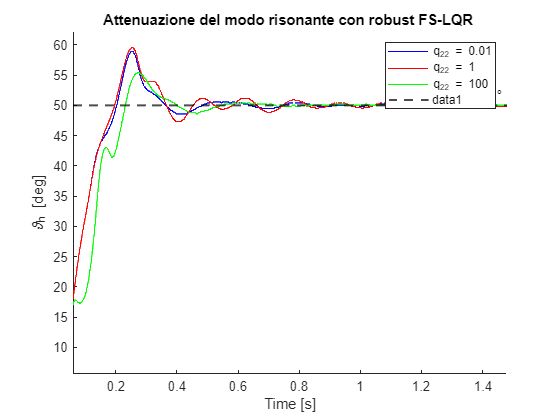


% grafico step 50 deg

load("lab3_fs_lqr_11_1.mat");
load("lab3_fs_lqr_11_2.mat");
load("lab3_fs_lqr_11_3.mat");

figure;
hold on 
plot(t1,tetha_h1,'b');
plot(t2,tetha_h2,'r');
plot(t3,tetha_h3,'g');
axis([0 20 0 70])
xlabel('Time [s]');
ylabel('\vartheta_h [deg]');
legend('q_{22} = 0.01', 'q_{22} = 1', 'q_{22} = 100');
yline(50, '--k', 'Riferimento 50°', 'LineWidth', 1.5);
title('Attenuazione del modo risonante con robust FS-LQR ');
hold off

xlim([0.14 6.21])
ylim([1.8 61.1])

xlim([0.06 1.48])
ylim([5.6 62.3])

## Stampa grafico tetha_d

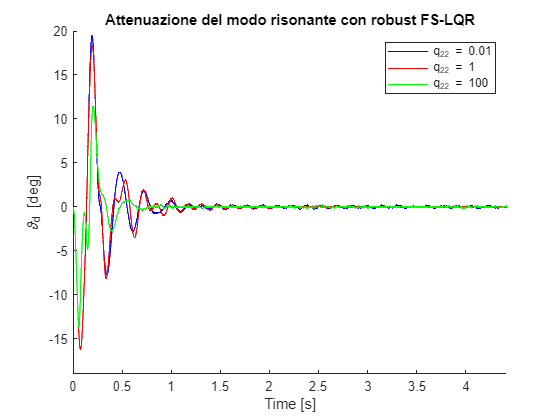


figure;
hold on 
plot(t1,tetha_d1,'b');
plot(t2,tetha_d2,'r');
plot(t3,tetha_d3,'g');
axis([0 20 -20 20])
xlabel('Time [s]');
ylabel('\vartheta_d [deg]');
legend('q_{22} = 0.01', 'q_{22} = 1', 'q_{22} = 100');
title('Attenuazione del modo risonante con robust FS-LQR');
hold off

xlim([0.00 4.42])
ylim([-19.0 20.0])

#### Step response parameters


step_50_wind_up_nominal_lqr_1 = stepinfo(tetha_h1, t1, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up_nominal_lqr_1);

         RiseTime: 0.1379
    TransientTime: 0.3049
     SettlingTime: 0.3049
      SettlingMin: 45.1800
      SettlingMax: 58.8600
        Overshoot: 17.7200
       Undershoot: 0
             Peak: 58.8600
         PeakTime: 0.2480



step_50_wind_up_nominal_lqr_2 = stepinfo(tetha_h2, t2, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up_nominal_lqr_2);

         RiseTime: 0.1320
    TransientTime: 0.4160
     SettlingTime: 0.4160
      SettlingMin: 45.1800
      SettlingMax: 59.5800
        Overshoot: 19.1600
       Undershoot: 0
             Peak: 59.5800
         PeakTime: 0.2500



step_50_wind_up_nominal_lqr_3 = stepinfo(tetha_h3, t3, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up_nominal_lqr_3);

         RiseTime: 0.1838
    TransientTime: 0.3218
     SettlingTime: 0.3218
      SettlingMin: 45.3600
      SettlingMax: 55.4400
        Overshoot: 10.8800
       Undershoot: 0
             Peak: 55.4400
         PeakTime: 0.2700



## Final table


q11_values = [0.01 ; 1 ; 100];

settling_times = [
    step_50_wind_up_nominal_lqr_1.SettlingTime;
    step_50_wind_up_nominal_lqr_2.SettlingTime;
    step_50_wind_up_nominal_lqr_3.SettlingTime;
];

overshoots = [
    step_50_wind_up_nominal_lqr_1.Overshoot;
    step_50_wind_up_nominal_lqr_2.Overshoot;
    step_50_wind_up_nominal_lqr_3.Overshoot;
];

Tabella_Risultati_LQR = table(q11_values, settling_times, overshoots, ...
    'VariableNames', {'Peso_q11', 'SettlingTime_sec', 'Overshoot_perc'});

disp('--- Risultati Test LQR con Azione Integrale ---');

--- Risultati Test LQR con Azione Integrale ---


disp(Tabella_Risultati_LQR);

    Peso_q11    SettlingTime_sec    Overshoot_perc
    ________    ________________    ______________

      0.01          0.30485             17.72     
         1          0.41599             19.16     
       100          0.32178             10.88     

